# Macro III: Problem Set 3

Deadline: Friday, 17/09/2018

Aluno: Bruno Tebaldi de Queiroz Barbosa (C174887)

Professor: Tiago Cavalcanti

Source code disponível em: [https://github.com/btebaldi/Macro3/tree/master/PSet_03](https://github.com/btebaldi/Macro3/tree/master/PSet_02)

## QUESTÃO 1 (f)

## LIMPEZA DE VARIAVEIS

clearvars
clc

## ITEM A DEFINICAO DE PARAMETROS

Defininimos os parametros que sao utilizados pelo problema

Econom_param.PeriodsPerYear = 6;
Econom_param.Beta_anual = 0.96;
Econom_param.Beta = (Econom_param.Beta_anual)^(1/Econom_param.PeriodsPerYear);
Econom_param.Sigma = 3;

eps = 1e-5;

## DEFINICAO DO GRID DE INCOME

Vamos Construir a matrix de transição baseada nas informações fornecidas

Income.Grid.N = 2;
Income.Grid.Max = 1;
Income.Grid.Min = 0.1;
Income.Values = linspace(Income.Grid.Max, Income.Grid.Min, Income.Grid.N);
Income.PI = [0.925 (1-0.925); 0.5 (1-0.5)];
Income.P_LongRun = CalculaLongoPrazo(Income.PI);

Logo a renda media de equilibrio no longo prazo sera.

Income.Average = Income.Values*Income.P_LongRun;
Income.Early = Income.Average * Econom_param.PeriodsPerYear;

A duração média do desemprego é dada por 1/f, onde f neste caso é 0.5. Sendo assim a duracao média do desemprego é dois periodos. Como o periodo é de dois meses, temos que a duração média de desemprego é de 4 meses.

## DEFINICAO DO GRID de ASSET

Borrow.Limit = -Income.Early;
Asset.Grid.N = 20;
Asset.Grid.Max = 3*Income.Average;
Asset.Grid.Min = Borrow.Limit;
Asset.Values = linspace(Asset.Grid.Min, Asset.Grid.Max, Asset.Grid.N);

## DEFINICAO DA TAXA DE JUROS

Inicia a taxa de juros

Econom_param.r_anual = 0.034;
Econom_param.r_start = ((1+Econom_param.r_anual)^(1/Econom_param.PeriodsPerYear))-1;
Econom_param.r_UpperLimit = 1/Econom_param.Beta - 1;
Econom_param.r_LowerLimit = 0;
Econom_param.r = Econom_param.r_start;

% parametro que indica se a taxa esta fixa ou nao.
Econom_param.r_IsFixed = 0;

## ACHANDO O EQUILIBRIO.

- Determinar um r inicial

- Resolver o Problema do Consumidor e obter a Politica

- Determinar Lambda

- Verificar se existe eequilibrio no mercado de assets

- Se nao ha equilibrio estabelecer novo r, (voltar a ponto 2) onde  $e>0 \rightarrow r_j+1 < r_j$  $e<0 \rightarrow r_j+1 > r_j$

nIntLimit = 1000;

for i=1:nIntLimit
    
    % (2) Resolve o Problema do consumidor
    [V0, U_Cube, Policy] = SolveConsumerProblem(Asset, Income, Econom_param);
    
    % (3) Determina a distribuicao estacionaria
    Lambda = ConstructLambda(Policy, Asset, Income);
    
    % (4) Determina demanda de assets
    Demanda = Lambda(:)' * Policy.AssetPrime.Values(:);
    
    % (5) Verifica se há equilibrio
    if abs(Demanda) < eps
        break;
    elseif Demanda > eps
        Econom_param.r_UpperLimit = Econom_param.r;
    elseif  Demanda < -eps
        Econom_param.r_LowerLimit = Econom_param.r;
    end
    
    % Caso a taxa esteja fixa não ha mais nada o que fazer
    if Econom_param.r_IsFixed == 1
        break;
    end
    
    % determina novo r
    r_old = Econom_param.r;
    Econom_param.r = (Econom_param.r_UpperLimit + Econom_param.r_LowerLimit)/2;
    
    % Caso a precisao da taxa seja muito pequena paramos a execucao.
    if abs(Econom_param.r - r_old) < eps^2
        break;
    end
    
    fprintf('Inter:%4d\tr_0: %1.6f\tr_1: %1.6f\tDem: %2.15f\n', i, r_old, Econom_param.r, Demanda);
end

Inter:   1	r_0: 0.005588	r_1: 0.002794	Dem: 1.691933671066469
Inter:   2	r_0: 0.002794	r_1: 0.001397	Dem: 0.094030769977306
Inter:   3	r_0: 0.001397	r_1: 0.000699	Dem: 0.094030769977306
Inter:   4	r_0: 0.000699	r_1: 0.001048	Dem: -0.664402180409014
Inter:   5	r_0: 0.001048	r_1: 0.001222	Dem: -0.262711239376189
Inter:   6	r_0: 0.001222	r_1: 0.001310	Dem: -0.262711239376189
Inter:   7	r_0: 0.001310	r_1: 0.001353	Dem: -0.262711239376189
Inter:   8	r_0: 0.001353	r_1: 0.001375	Dem: -0.262711239376189
Inter:   9	r_0: 0.001375	r_1: 0.001364	Dem: 0.094030769977306
Inter:  10	r_0: 0.001364	r_1: 0.001359	Dem: 0.094030769977306
Inter:  11	r_0: 0.001359	r_1: 0.001356	Dem: 0.094030769977306
Inter:  12	r_0: 0.001356	r_1: 0.001355	Dem: 0.094030769977306
Inter:  13	r_0: 0.001355	r_1: 0.001355	Dem: -0.262711239376189
Inter:  14	r_0: 0.001355	r_1: 0.001356	Dem: -0.262711239376189
Inter:  15	r_0: 0.001356	r_1: 0.001356	Dem: 0.094030769977306
Inter:  16	r_0: 0.001356	r_1: 0.001356	Dem: -0.262711239376189



% Limpa variaveis nao utilizadas
clear nIntLimit r_old

## GRAFICO DA FUNCAO POLITICA DE $A_{t+1}$ CONTRA $A_{t}$

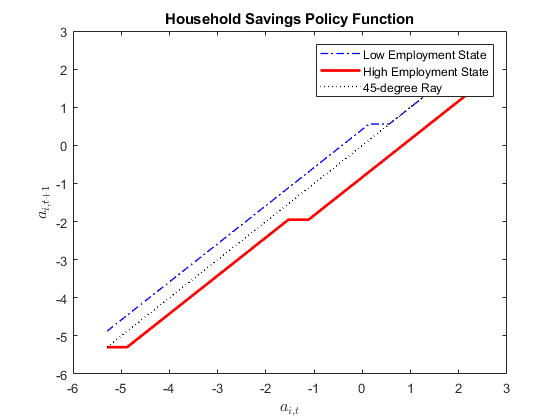

fig1 = figure();
plot(Policy.AssetDomain, Policy.AssetPrime.Values(:,1),'b-.','LineWidth',1); hold on;
plot(Policy.AssetDomain, Policy.AssetPrime.Values(:,2),'r','LineWidth',2); hold on;
plot(Policy.AssetDomain, Policy.AssetDomain,'k:','LineWidth',1); hold off;
legend({'Low Employment State','High Employment State','45-degree Ray'});
title('Household Savings Policy Function');
xlabel('$a_{i,t}$','FontSize',12,'Interpreter','latex');
ylabel('$a_{i,t+1}$','FontSize',12,'Interpreter','latex');

## SIMULACAO DE LIFE HISTORY

define uma funcao que indica, dado um valor de asset, qual o valor do grid que mais se aproxima do valor informado. Em outras palavras informa aonde um valor fornecido estaria no grid.

Policy.AssetIndexFunction = @(value) round((value-Policy.AssetDomain(1))/(Policy.AssetDomain(2)-Policy.AssetDomain(1))) + 1;

% Total de simulacoes
Simulation.N = 10000;

% Nivel inicial de ativos
asset_0 = 0;

% Estado inicial: Empregado.
Simulation.S0 = 1;
Simulation.Wage = 1;

% Inicializa os vetores da simulacao.
Simulation.Asset = nan(Simulation.N,1);
Simulation.AssetIndex = nan(Simulation.N,1);
Simulation.Consumption = nan(Simulation.N,1);
Simulation.Investment = nan(Simulation.N,1);
Simulation.LaborIncome = nan(Simulation.N,1);
Simulation.AssetIncome = nan(Simulation.N,1);
Simulation.Shock = nan(Simulation.N,1);

% Gera uma cadeia de choques no salario
[stateValue, stateIndex] = MarkovSimulation(Income.PI, Simulation.N, Income.Values, Simulation.S0);

for i = 1:Simulation.N
    % pega o estado do choque.
    Simulation.Asset(i) = asset_0;
    Simulation.AssetIndex(i) = Policy.AssetIndexFunction(asset_0);
    
    Simulation.Shock(i) = stateValue(i);
    
    % determina o investimento baseado no estado atual (asset\capital e
    % choque)
    Simulation.Investment(i) = Policy.AssetPrime.Values(Simulation.AssetIndex(i), stateIndex(i));
    
    % Determina a renda proveniente do trabalho
    Simulation.LaborIncome(i) = Simulation.Wage*stateValue(i);
    
    % Determina a renda proveniente do rendimento dos assets
    Simulation.AssetIncome(i) = (1 + Econom_param.r)*Simulation.Asset(i);
    
    % Determina o consumo pela equacao de equilibrio
    Simulation.Consumption(i) = Simulation.AssetIncome(i) + Simulation.LaborIncome(i) - Simulation.Investment(i);
    
    % Atualiza o asset
    asset_0 = Simulation.Investment(i);
end
fprintf('DONE\n');

DONE


## GRAFICOS

Grafico de investimento vs consumo

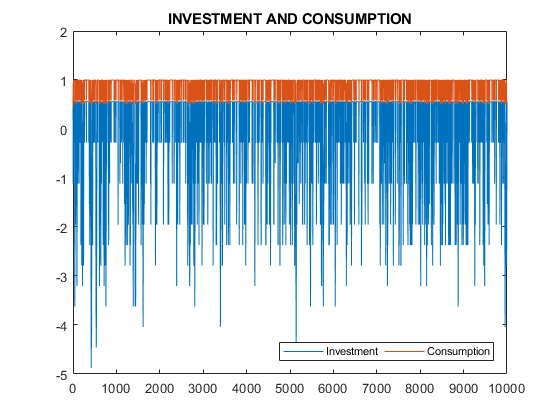

x = 1:Simulation.N;
plot(x, Simulation.Investment, x, Simulation.Consumption);
title('INVESTMENT AND CONSUMPTION');
legend({'Investment','Consumption'},'FontSize', 8, 'Location','southeast', 'Orientation','Horizontal');

Covariancia de consumo e investimento

cov(Simulation.Consumption,Simulation.Investment)

ans =     0.0351    0.1023
    0.1023    0.8041


Grafico de renda vs consumo

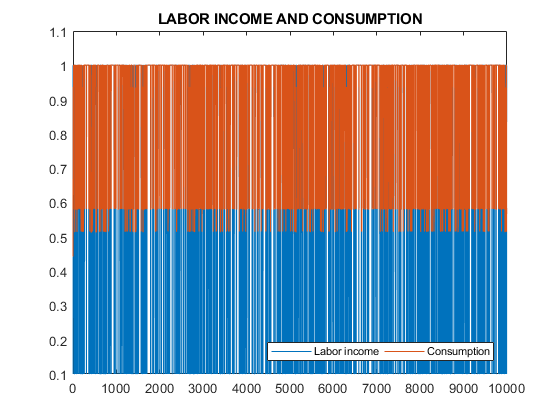

figure
plot(x, Simulation.LaborIncome, x, Simulation.Consumption);
title('LABOR INCOME AND CONSUMPTION');
legend({'Labor income','Consumption'},'FontSize', 8, 'Location','southeast', 'Orientation','Horizontal');

Covariancia de renda e consumo

cov(Simulation.LaborIncome, Simulation.Consumption)

ans =     0.0951    0.0044
    0.0044    0.0351


Grafico de renda vs investimento

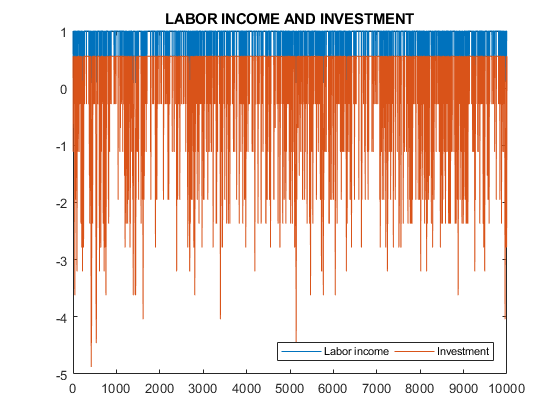

figure
plot(x, Simulation.LaborIncome, x, Simulation.Investment);
title('LABOR INCOME AND INVESTMENT');
legend({'Labor income','Investment'},'FontSize', 8, 'Location','southeast', 'Orientation','Horizontal');

Covariancia de renda e investimento

cov(Simulation.LaborIncome, Simulation.Investment)

ans =     0.0951    0.1619
    0.1619    0.8041


Grafico de riqueza total

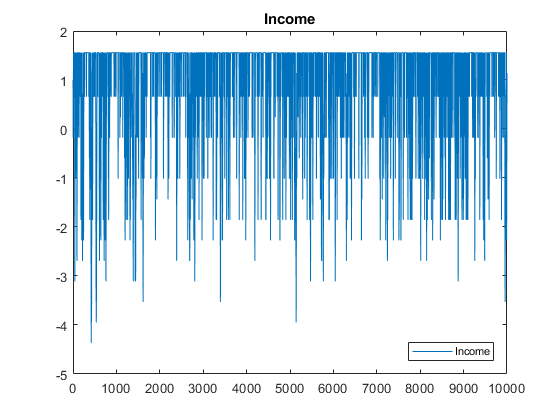

figure
plot(x, Simulation.LaborIncome + Simulation.AssetIncome);
title('Income');
legend({'Income'},'FontSize', 8, 'Location','southeast', 'Orientation','Horizontal');

Histograma de ativos

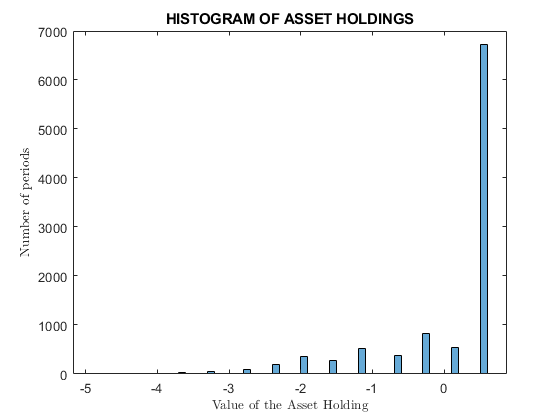

figure
histogram(Simulation.Investment)
title('HISTOGRAM OF ASSET HOLDINGS')
xlabel('Value of the Asset Holding','FontSize',10,'Interpreter','latex');
ylabel('Number of periods','FontSize',10,'Interpreter','latex')


% limpa variaveis
clear x

## CALCULO DOS VALORES EXPERADOS

average value of asset holdings

mean(Simulation.Asset)

ans = 0.0567

Average decline in consumption in response to entering unemployment

Delta.Consumption = Simulation.Consumption(2:end) - Simulation.Consumption(1:end-1);
Delta.Shock =  Simulation.Shock(2:end) - Simulation.Shock(1:end-1);
mean(Delta.Consumption(Delta.Shock < 0))

ans = 0.0313


clear Delta

Average consumption conditional on (i) employed; (ii) unemployed; (iii) unemployed for the last 12 months.

mean(Simulation.Consumption(Simulation.Shock==1))

ans = 0.8835

mean(Simulation.Consumption(Simulation.Shock==0.1))

ans = 0.8415


A = (Simulation.Shock==0.1)';
B = [1 1 1 1 1 1];
Unemployed6m = strfind(A,B)';

Consumption6Months = 0;
TotalPeriods = size(Unemployed6m,1);
for i=1:TotalPeriods
    Consumption6Months = Consumption6Months + mean(Simulation.Consumption(Unemployed6m(i):Unemployed6m(i)+6));
end
Consumption6Months/TotalPeriods

ans = 0.6497


clear A B Consumption6Months TotalPeriods Unemployed6m

## %% INCOME DISTRIBUTION

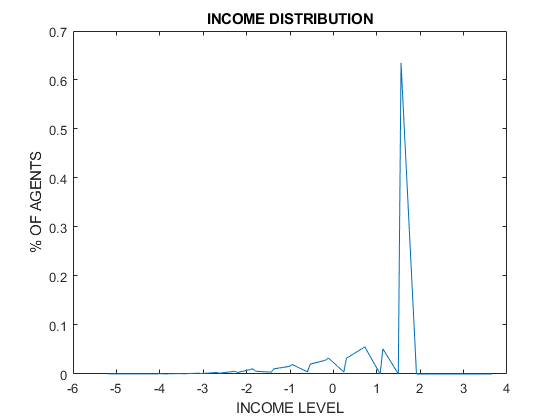

Total_Income =  ((1+Econom_param.r)*Asset.Values)'*ones(1,Income.Grid.N) + ones(1,Asset.Grid.N)'*Income.Values; 
[sortedIncome, index] = sort(Total_Income(:));
lambda_aux = Lambda(:);

figure
plot(sortedIncome, lambda_aux(index));
title('INCOME DISTRIBUTION');
xlabel('INCOME LEVEL');
ylabel('% OF AGENTS');

## STANDARD MEASURES FOR WEALTH DISPERSION

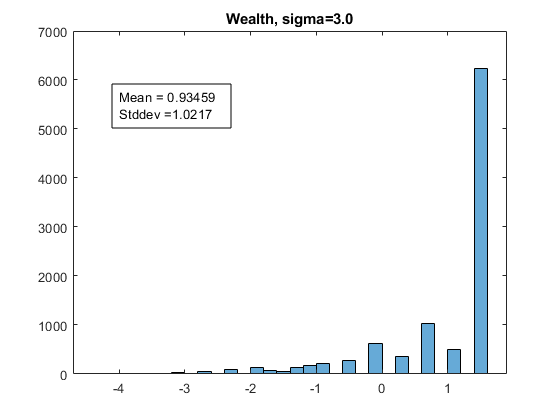

mean_w = mean(Simulation.AssetIncome+Simulation.LaborIncome);
stdr_w = std(Simulation.AssetIncome+Simulation.LaborIncome);

figure
histogram(Simulation.AssetIncome+Simulation.LaborIncome);
annotation('textbox',[.2 .3 .4 .5],...
    'String',{['Mean = ' num2str(mean_w)],['Stddev =' num2str(stdr_w)]},...
'FitBoxtoText','on');
title(sprintf('Wealth, sigma=%1.1f',Econom_param.Sigma));